Создайте матрицу data = [1 2 3;4 5 6;7 8 9] и выведите в переменную x сначала вторую строку матрицы data, потом - третий столбец.

data = [1 2 3;4 5 6;7 8 9];
x = data(2,:)

x =      4     5     6


x = data(:,3)

x =      3
     6
     9


Присвойте переменной х случайное значение, и затем, если оно больше либо равно 0.5, присвойте его переменной y, иначе присвойте переменной у значение 1-х.

x = rand

x = 0.1270

if x >= 0.5
    y = x
else
    y = 1 -x
end

y = 0.8730

Найдите предел lim((1-x)/ln(x)) при x->1

syms x;
limit((1-x)/log(x),x,1)

$$ans = -1$$

Найдите предел lim((1+1/x)^(a*x)) при x->Inf

syms a;
limit((1+1/x)^(a*x),x,inf)

$$ans = {\mathrm{e}}^{a}$$

Найдите предел lim((x-a)/ln(x-a+1)) при x->a

limit((x-a)/log(x-a+1),x,a)

$$ans = 1$$

Постройте графики функций одной переменной f(x)=(sin(x))/x и g(x)=(e^(-x))*cos(x) на отрезке [0.01, 2pi]. Выведите графики различными способами: в отдельные графические окна, в одно окно на одни оси, в одно окно на отдельные оси. Подпишите легенду, оси, заголовки. Нанесите сетку.

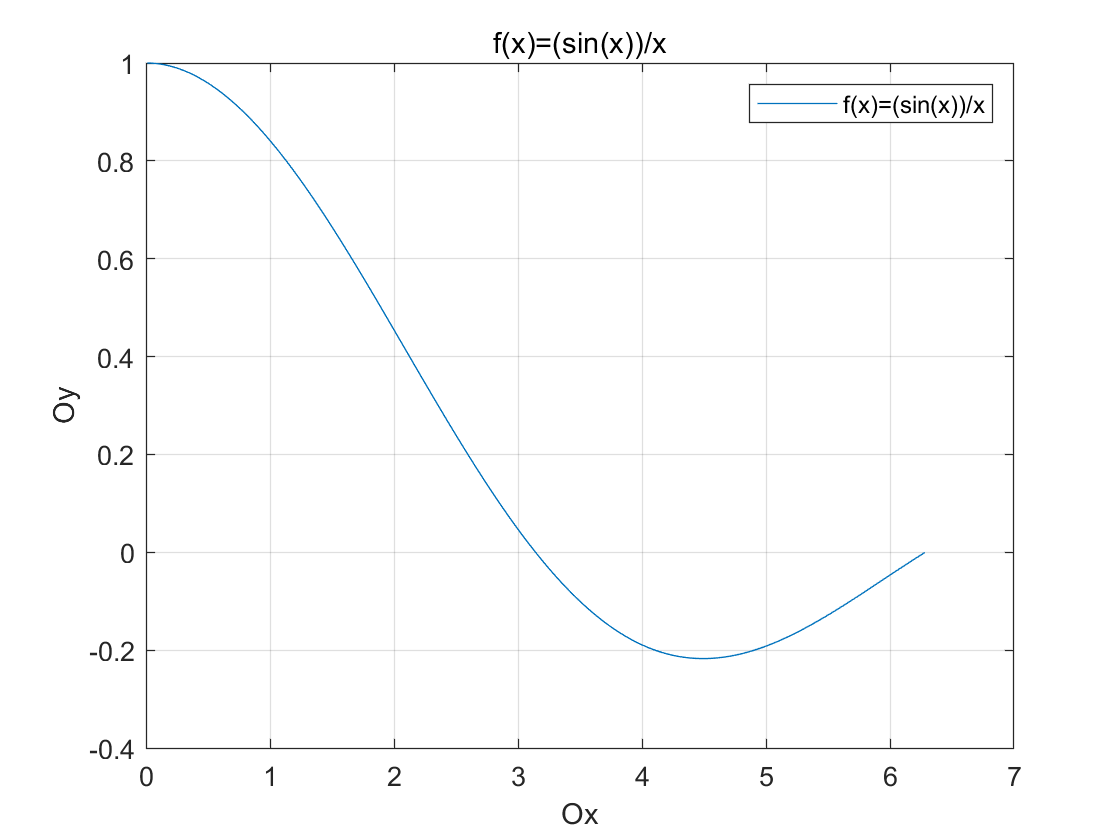

x = 0.01:0.01:2*pi;
y1 = sin(x)./x;
y2 = exp(-x) .* cos(x);
figure
plot(x,y1)
title('f(x)=(sin(x))/x')
xlabel('Ox')
ylabel('Oy')
legend('f(x)=(sin(x))/x')
grid on

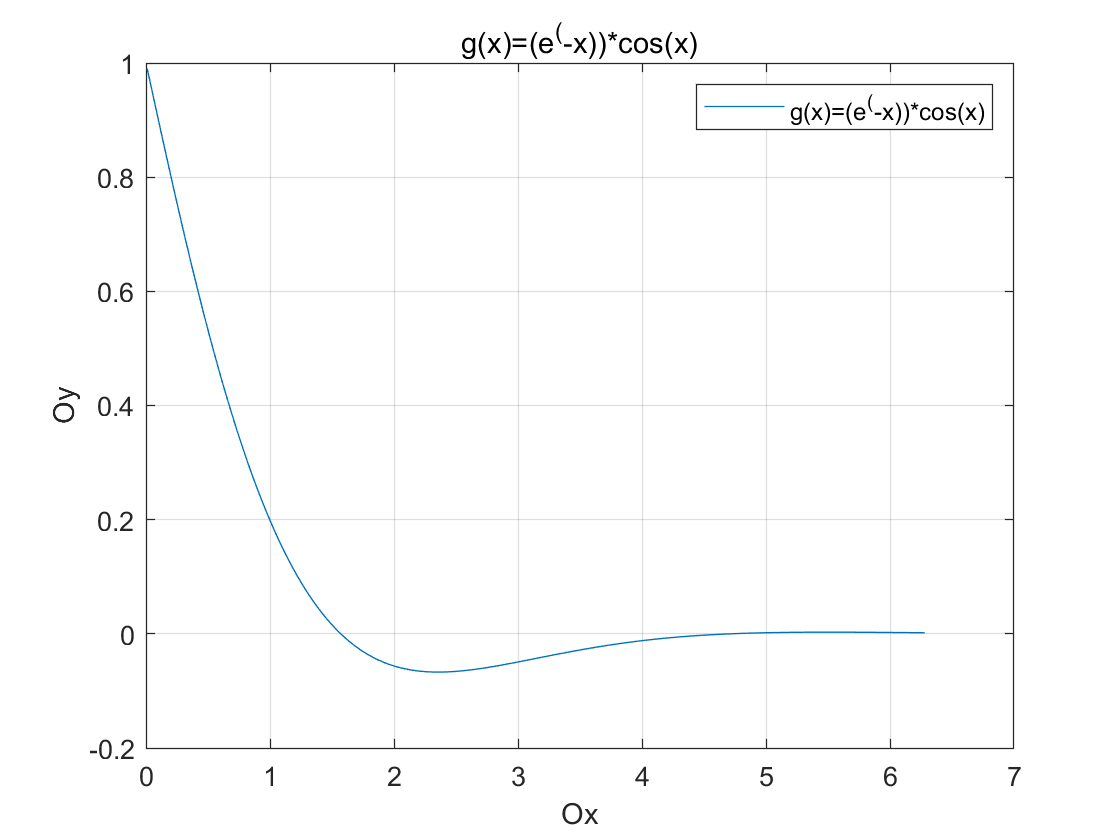

figure
plot(x,y2)
title('g(x)=(e^(-x))*cos(x)')
xlabel('Ox')
ylabel('Oy')
legend('g(x)=(e^(-x))*cos(x)')
grid on

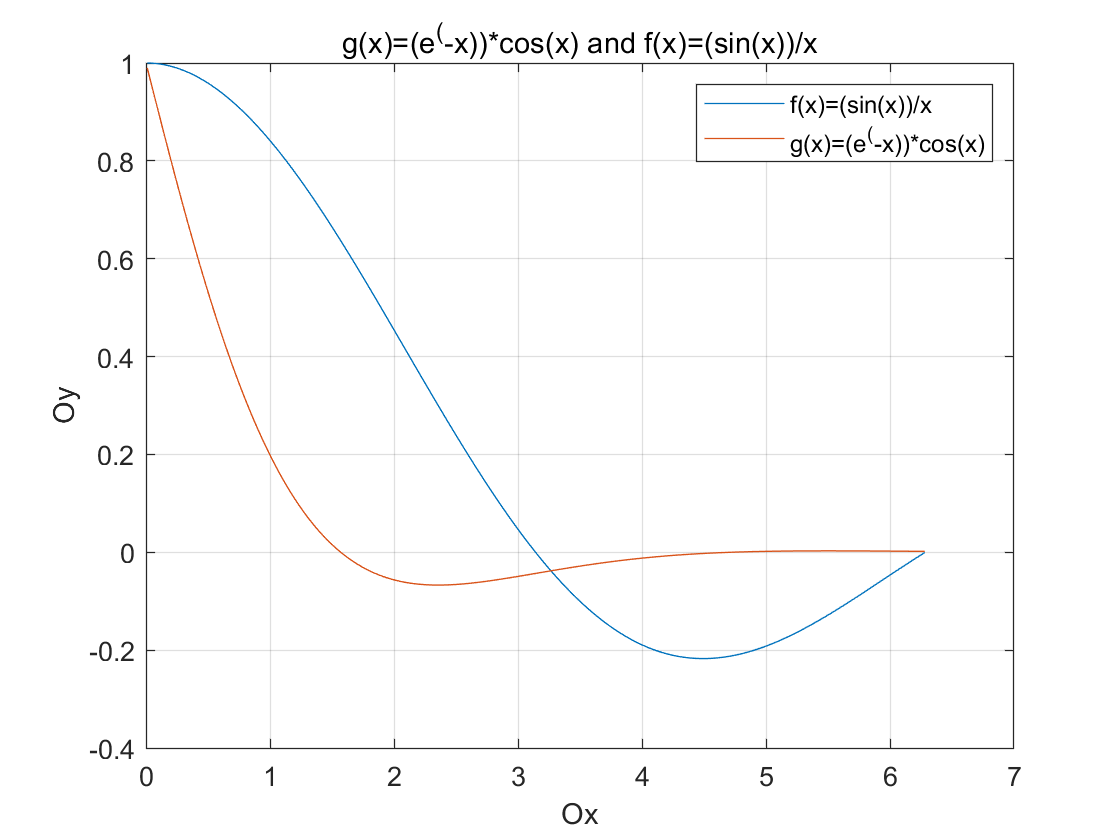

figure
plot(x,y1)
hold on
plot(x,y2)
title('g(x)=(e^(-x))*cos(x) and f(x)=(sin(x))/x')
xlabel('Ox')
ylabel('Oy')
legend('f(x)=(sin(x))/x','g(x)=(e^(-x))*cos(x)')
hold off
grid on

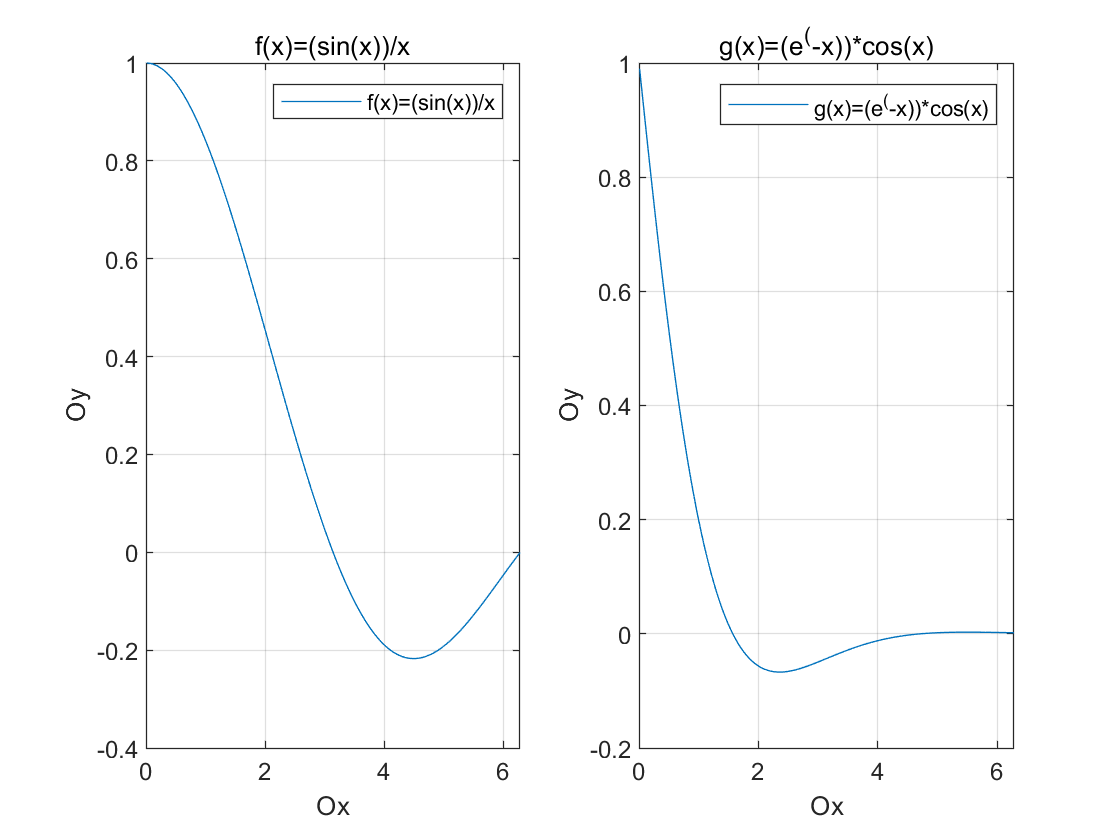

figure
subplot(1,2,1);
plot(x,y1)
title('f(x)=(sin(x))/x')
xlabel('Ox')
ylabel('Oy')
legend('f(x)=(sin(x))/x')

grid on
subplot(1,2,2)
plot(x,y2)
title('g(x)=(e^(-x))*cos(x)')
xlabel('Ox')
ylabel('Oy')
legend('g(x)=(e^(-x))*cos(x)')

grid on

Постройте каркасную поверхность z(x,y)=2*sin(2pix)*cos(2piy)*(1-y^2)*x*(1-x) на прямоугольной области x: [-3,3], y: [-4,4]. Разверните поверхность и сделайте её прозрачной, подобрав угол и шаг так, чтобы прозрачность была видна.

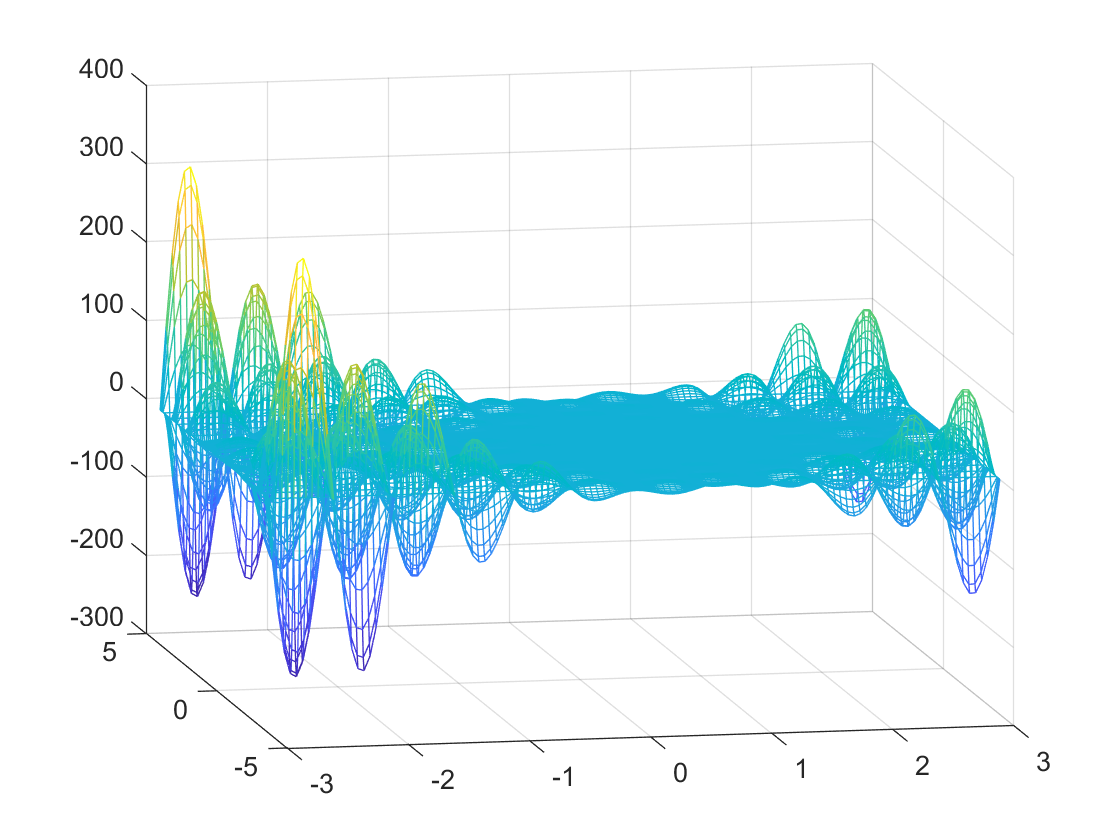

figure
[x, y] = meshgrid(-3:0.05:3,-4:0.05:4);
z = 2 .* sin(2 * pi .* x) .* cos(2 * pi .* y) .* (1 -(y .* y)) .* x .* (1 - x);
mesh(x, y, z, 'FaceAlpha', '0')
view(-11, 12)

Постройте гладкую освещённую поверхность эллипсоида, заданного соотношениями x(u,v)=cos(u)*cos(v), y(u,v)=0,9*cos(u)*sin(v), z(u,v)=0,4*sin(u), u,v: [-2pi,2pi] с шагом 0,01*pi (v – вектор-строка, u – вектор-столбец).

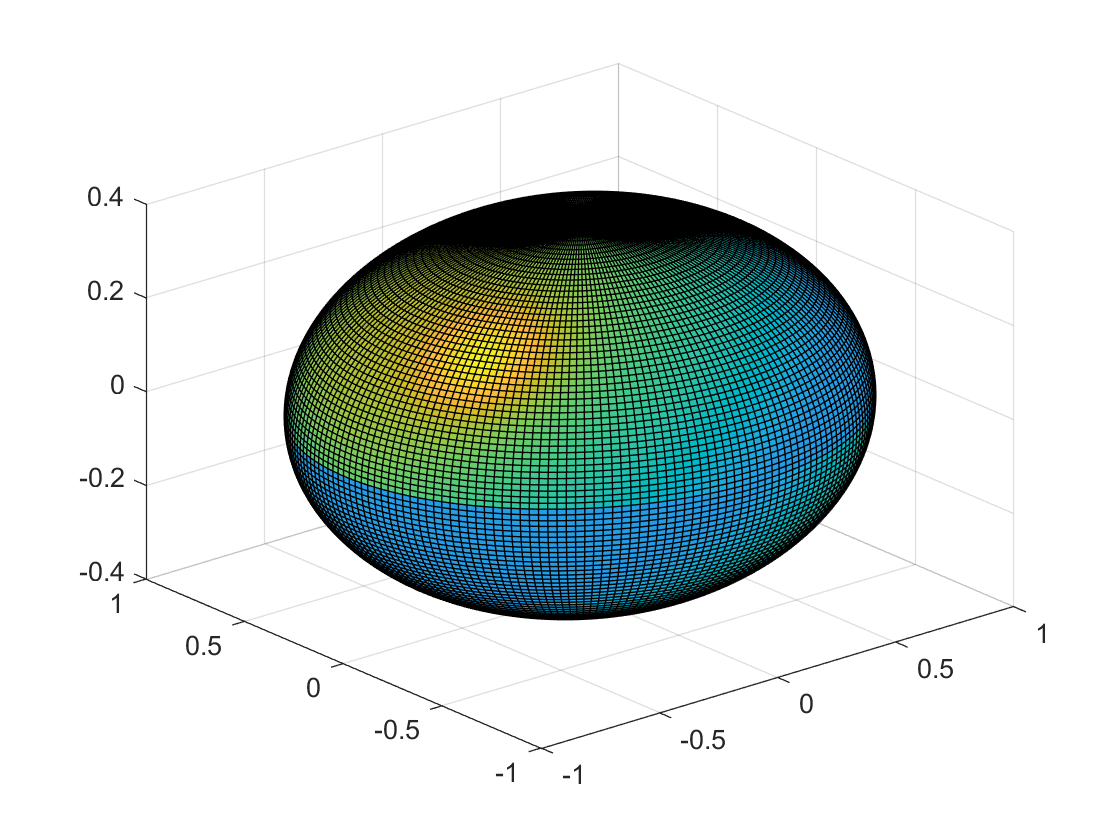

figure
[u,v] = meshgrid(-2*pi:0.01*pi:2*pi);
x = cos(u) .* cos(v);
y = 0.9.*cos(u).*sin(v);
z = 0.4 .* sin(u);
surfl(x, y, z, [-90 45])

Постройте параметрически заданную поверхность, определённую зависимостями x(u,v)=2*u*cos(v), y(u,v)=3*u*sin(v), z(u,v)=u, где u,v: [-4pi,4pi] с шагом 0,1*pi (v – вектор-строка, u – вектор-столбец).

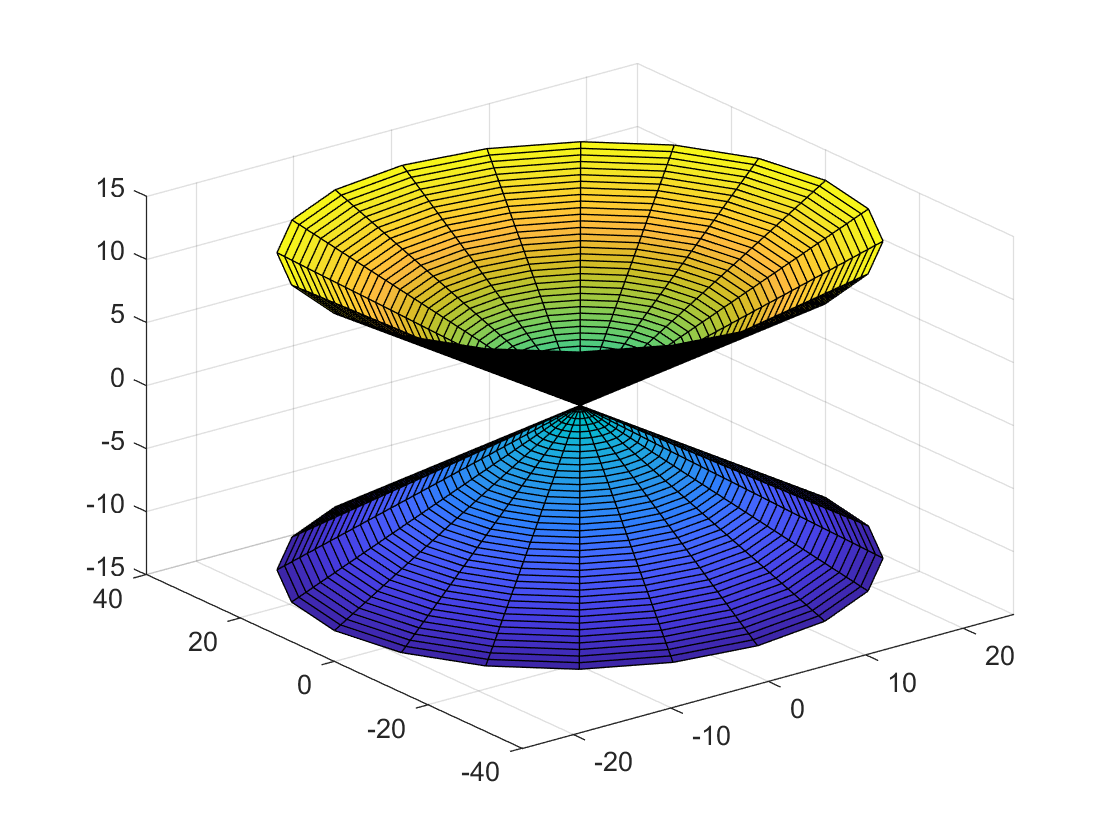

figure
[u,v] = meshgrid(-4*pi:0.1*pi:4*pi);
x = 2 .* u .* cos(v);
y = 3 .* u .* sin(v);
z = u;
surf(x,y,z)

Постройте график трёхмерной линии x=(t/(1-t))*sin(t), y=(t/(1+t))*cos(t), z=t, t: [0,100] с шагом 0.01.

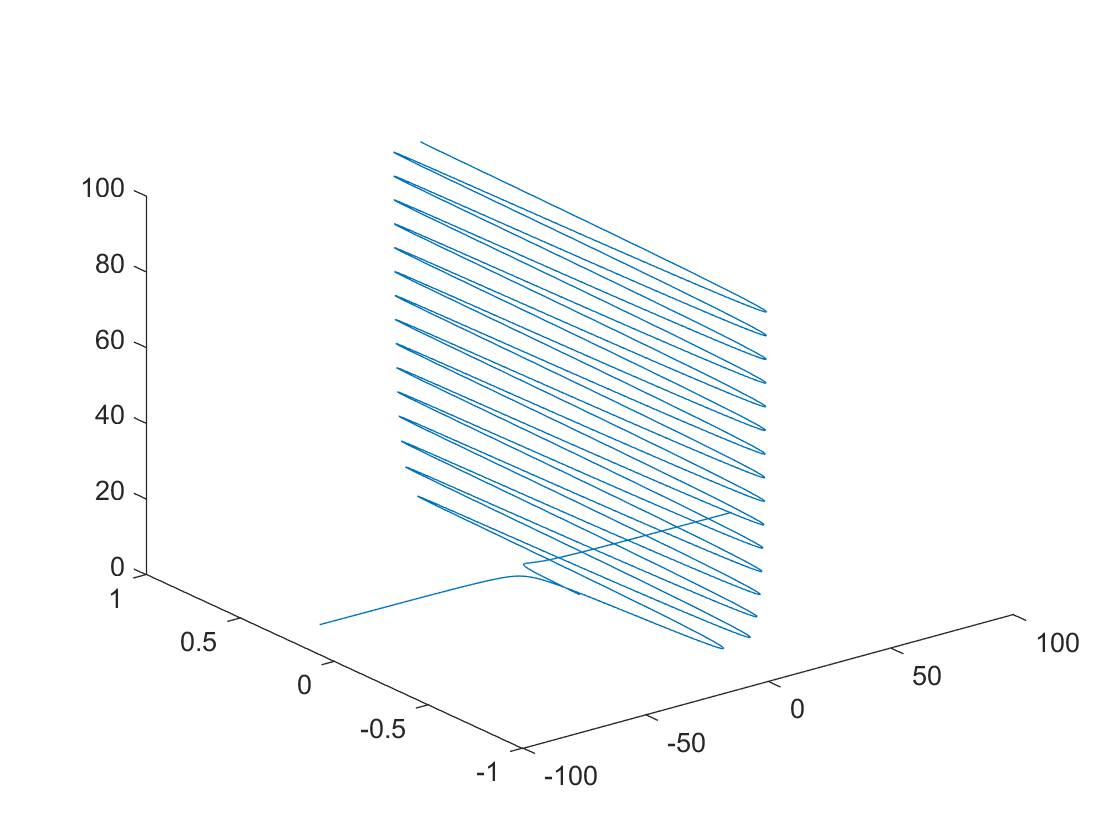

figure
t = [0:0.01:100];
x=(t./(1-t)).*sin(t);
y=(t./(1+t)).*cos(t);
z = t;
plot3(x,y,z)